load('AnalogData.mat');
rawData = out.AnalogData

rawData =           45        2142
          45        2144
          45        2123
          45        2155
          45        2143
          45        2136
          45        2128
          45        2128
          45        2145
          45        2133


% Data from Magnetic Sensor
Nround = 13; % 45 : -3 : 9
Nsample = 501;

% Manipulate matrix
distanceData = rawData(:, 1)

distanceData =     45
    45
    45
    45
    45
    45
    45
    45
    45
    45


analogs = rawData(:, 2)

analogs =         2142
        2144
        2123
        2155
        2143
        2136
        2128
        2128
        2145
        2133


anaData = reshape(analogs, [Nsample, Nround])'

anaData =         2142        2144        2123        2155        2143        2136        2128        2128        2145        2133        2137        2134        2145        2130        2163        2139        2131        2129        2131        2130        2124        2125        2122        2126        2121        2133        2165        2138        2123        2131        2138        2135        2125        2127        2139        2132        2125        2133        2170        2124        2144        2128        2148        2133        2139        2142        2141        2131        2132        2123
        2178        2176        2161        2164        2150        2144        2140        2148        2150        2151        2159        2185        2136        2148        2147        2162        2153        2142        2149        2136        2151        2151        2148        2153        2178        2151        2135        2144        2157        2146        2154        2141     


% to be used
anaData = cast(anaData, "double");
voltData = anaData .* 3.3 ./ 4096.0

voltData =     1.7257    1.7273    1.7104    1.7362    1.7265    1.7209    1.7145    1.7145    1.7281    1.7185    1.7217    1.7193    1.7281    1.7161    1.7427    1.7233    1.7169    1.7153    1.7169    1.7161    1.7112    1.7120    1.7096    1.7128    1.7088    1.7185    1.7443    1.7225    1.7104    1.7169    1.7225    1.7201    1.7120    1.7136    1.7233    1.7177    1.7120    1.7185    1.7483    1.7112    1.7273    1.7145    1.7306    1.7185    1.7233    1.7257    1.7249    1.7169    1.7177    1.7104
    1.7547    1.7531    1.7410    1.7435    1.7322    1.7273    1.7241    1.7306    1.7322    1.7330    1.7394    1.7604    1.7209    1.7306    1.7298    1.7418    1.7346    1.7257    1.7314    1.7209    1.7330    1.7330    1.7306    1.7346    1.7547    1.7330    1.7201    1.7273    1.7378    1.7290    1.7354    1.7249    1.7402    1.7314    1.7290    1.7572    1.7241    1.7378    1.7354    1.7233    1.7281    1.7338    1.7153    1.7354    1.7241    1.7338    1.7362    1.7596    1.74

voltData = voltData(end:-1:1, :) % reverse order to 9 ... 45

voltData =     3.2710    3.2702    3.2694    3.2710    3.2702    3.2694    3.2726    3.2718    3.2710    3.2710    3.2694    3.2718    3.2702    3.2710    3.2742    3.2710    3.2702    3.2662    3.2726    3.2718    3.2694    3.2710    3.2702    3.2710    3.2686    3.2694    3.2670    3.2702    3.2718    3.2718    3.2702    3.2710    3.2702    3.2710    3.2694    3.2758    3.2710    3.2702    3.2702    3.2694    3.2702    3.2686    3.2710    3.2694    3.2702    3.2718    3.2710    3.2710    3.2670    3.2710
    3.2734    3.2742    3.2702    3.2726    3.2718    3.2702    3.2726    3.2710    3.2718    3.2718    3.2702    3.2758    3.2718    3.2710    3.2718    3.2718    3.2726    3.2718    3.2726    3.2726    3.2718    3.2702    3.2702    3.2710    3.2726    3.2718    3.2718    3.2718    3.2718    3.2718    3.2718    3.2718    3.2718    3.2718    3.2718    3.2726    3.2750    3.2718    3.2670    3.2718    3.2702    3.2718    3.2718    3.2718    3.2726    3.2726    3.2710    3.2710    3.27


meanVoltData = mean(voltData, 2) %%((mean(voltData, 2)/3.3) *100)

meanVoltData =     3.2706
    3.2720
    3.2716
    2.9003
    2.3470
    2.0707
    1.9318
    1.8527
    1.8022
    1.7698


%meanVoltData = meanVoltData(end:-1:1) % reverse order
measureX = 9 : 3 : 45

measureX =      9    12    15    18    21    24    27    30    33    36    39    42    45


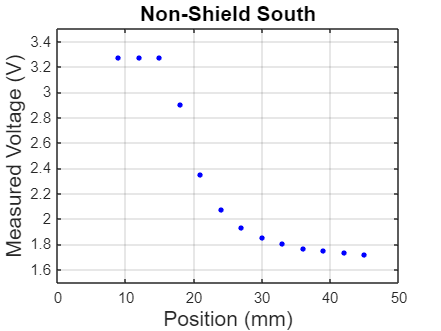

% Plotting
measureGraph = plot(measureX, meanVoltData, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
% ตกแต่ง
xticks(0:10:50);
xticklabels(0:10:50);
yticks(0:0.2:3.4);
yticklabels(0:0.2:3.4);
grid on;
title('Non-Shield South', 'FontSize', 14);
xlabel('Position (mm)', 'FontSize', 14); 
ylabel('Measured Voltage (V)', 'FontSize', 14); 

% Calculate Errors
stdErr = 2 .* std(voltData, 0, 2) % plot with 2SD for 95% confidence interval

stdErr =     0.0031
    0.0029
    0.0029
    0.0136
    0.0195
    0.0185
    0.0188
    0.0170
    0.0170
    0.0166


% 1SD is also OK

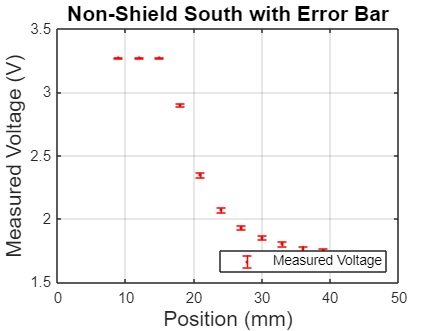

% Plotting Graph with Error

%measureGraph;
%hold on;

errorbar(measureX, meanVoltData, stdErr, 'or', 'LineWidth', 1, 'MarkerSize', 1, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); 
hold off;
% Add on
xticks(0:10:100);
xticklabels(0:10:100);
grid on;
title('Non-Shield South with Error Bar', 'FontSize', 14);
xlabel('Position (mm)', 'FontSize', 14); 
ylabel('Measured Voltage (V)', 'FontSize', 14); 
legend('Measured Voltage','Location', 'southeast');